clear; % hello!

# **AERO21111 Space Systems - 11091029**

# Tutorial 1 - Propulsion Sensitivity and Mission Analysis

## Introduction

This coursework outlines the mission design process of the Sentinel 6-B satellite, the successor to the Sentinel 6-A earth observation satellite, which was used for sea level measurements. For this tutorial, I will conduct a sensitivity analysis to find how much fuel will be required for the spacecraft's final deorbit burn by comparing and plotting ranges of specific impusles and velocity change requirements. This is a crucial part of the mission as space debris is becoming an increasingly serious problem, so including a burn to remove the spacecraft from its orbit is necessary to ensure that the spacecraft does not impede any future missions. 

### Task 1 - Identify equation relating fuel mass, Δv, and Isp

To find the fuel mass required for the mission's deorbit burn, we first have to find an equation that relates our given variables (Isp, Δv) with the fuel mass. 

Equation (5.30)

#### 
$$\Delta v=I_{\textrm{sp}} g*\ln \left(\frac{m_0 }{m_1 }\right)-\frac{D}{m}\Delta t-g*\sin \left(\gamma \Delta t\right)$$


We can assume that any gravitational effects ($g\left(\sin \left(\gamma \Delta t\right)\right)$ and drag effects ($\frac{D}{m}\Delta t$) are negligible as the spacecraft is operating at an altitude high above the earth's atmosphere and far enough away. For this reason, we can exclude the final two terms from the above equation. 

Specific Impulse Range $I_{\textrm{sp}}$

    
$$I_{\textrm{sp}} =200s-300s$$


Gravational acceleration $g$

    
$$g=9\ldotp 81{\textrm{ms}}^{-2}$$


Initial mass $m_0$

    
$$m_0 =m_{\textrm{fuel}} +m_1$$


Final mass $m_1$

    
$$m_1 =m_{\textrm{dry}} =1000\textrm{kg}$$


We can find our expression for fuel mass by rearranging this equation to yield the following result: 

    
$$m_{\textrm{fuel}} =m_{\textrm{dry}} *\left(e^{\frac{\Delta v}{I_{\textrm{sp}} g}} -1\right)$$


### Task 2 - Establish Necessary Input Values

Now that we have identified the correct equation and rearranged it for the mass of fuel we are trying to find, we must define the input values for MATLAB. 

dry_mass = 1000; % [kg] Satellite dry mass

The two following arrays are for Specific Impulse $I_{\textrm{sp}}$ and Change in Velocity $\Delta v$ and they range from 200s to 300s in increments of 1s and 1000m/s and 3000m/s in increments of 10m/s respectively. 

Isp = linspace(200,300); % [s] Specific impulse in 100 increments
dv = linspace(1000,3000); % [m/s] Change in velocity Δv in 100 increments

### Task 3 - Turn $I_{\textrm{sp}}$ and $\Delta v$ into a 2D Mesh

The next step is to create a 2D mesh grid representing the relation between Specific Impulse and Change in Velocity. This will be used to create a surf plot and find the fuel mass required for the deorbit burn. We can use the built in **meshgrid** MATLAB function to create this 2D mesh. 

[Isp, dv] = meshgrid (Isp, dv); % Creates an equally sized array of ISP and Δv

### Task 4 - Calculate the Required Fuel Mass

To calculate the required fuel mass, all we need to do is plug our values into the equation that was rearranged above. 


$$m_{\textrm{fuel}} =m_{\textrm{dry}} *\left(e^{\frac{\Delta v}{I_{\textrm{sp}} g}} -1\right)$$


m_fuel = dry_mass*(exp(dv./(Isp*9.81))-1); % [kg] Array for possible fuel masses given a range ISP and Δv

### Task 5 - Generate a Surface Plot

The built in MATLAB function **surf** allows us to create a plot which allows us to conduct a sensitivity analysis for the mass of fuel required given a specific Isp and required Δv. 

s = surf(Isp, dv, m_fuel); % Creates the surface plot object
view(2); % Makes the surf chart 2d

Now, it is necessary to properly label and title the chart. 

title('Specific Impulse (s) VS Delta V required (m/s)'); % Titles the plot
xlabel('Specific Impulse (Isp) (s)'); % Label of the x axis
ylabel('Delta V (dv) (m/s)'); % Label of the y axis

The built-in MATLAB function **yline** and **xline** as well as **datatip** are useful for pin-pointing the necessary fuel mass. I have generated a red dotted **yline** for all points where $\Delta v=1300{\textrm{ms}}^{-1}$ and a red dotted **xline** for all points where $I_{\textrm{sp}} =230s$. The function **datatip** shows the X, Y, and Z values, corresponding to Isp, Δv, and fuel mass for the point on the surface plot where $\Delta v=1300{\textrm{ms}}^{-1}$ and $I_{\textrm{sp}} =230s$ and the resultant fuel mass of 780kg. 

yline(1300, 'r:'); % Plots a horizontal line at Isp = 230s
xline(230, 'r:'); % Plots a vertical line at Δv = 1300m/s
datatip(s,230,1300); % Creates a datatip at Δv = 1300m/s and Isp = 230s

A descriptive colourbar has been included to clarify what the colours on the surf correspond to in terms of fuel mass required. 

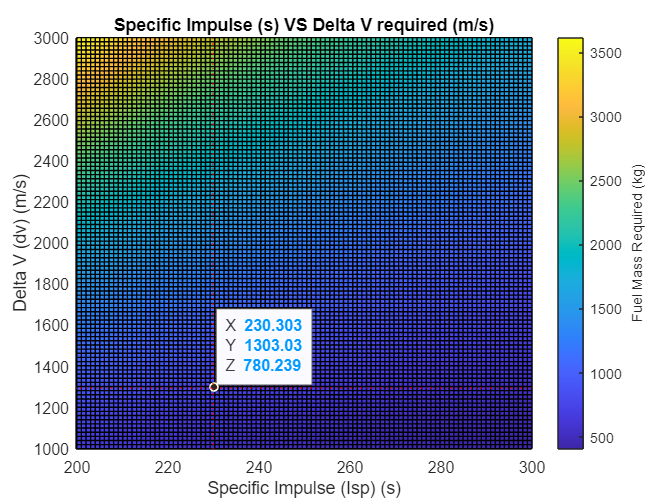

c = colorbar; % Creates a colourbar object for fuel mass required
c.Label.String = 'Fuel Mass Required (kg)'; % Labels the colourbar object 

### Task 6 - Identify Total Mass

Total mass of the spacecraft, $m_{\textrm{sc}}$, is the sum of wet and dry masses. Fuel mass was just found at 779kg from the surface plot, and this makes up the wet mass. The dry mass is 1000kg, as was stated before. 


$$\begin{array}{l}
m_{\textrm{sc}} =m_{\textrm{dry}} +m_{\textrm{fuel}} \\
m_{\textrm{sc}} =1000+779=1779\textrm{kg}
\end{array}$$


fuel_mass = dry_mass*(exp(1300/(230*9.81))-1); % [kg] Mass of fuel

However, due to this analysis containing many assumptions, some of which would have considerable impacts on the real mass requirements of the mission, I have added a 10% safety margin of fuel. 


$$m_{\textrm{sc}} =m_{\textrm{dry}} +1\ldotp 1*m_{\textrm{fuel}} =1857\textrm{kg}$$


m_sc = dry_mass + 1.1*fuel_mass; % [kg] Total SC mass

### Task 7 - Identify a Launch Vehicle and Launch Site

A suitable launch vehicle that can place this mission's payload into its operational orbit must be selected. We have been given the option of four different launch providers as well as seven different launch locations. 

#### Mass

All four launch vehicles can support the mass of our satellite. 

#### Reliability

The reliability of each launch vehicle is provided below: 

- Falcon 9 v1.2 = 98.4%

- Ariane V = 95.4%

- Atlas V = 98.9%

- Delta IV Medium = 94.9%

Due to the Delta IV Medium having a launch reliability of under 95%, I have decided to disregard it from the launch vehicle selection process as it cannot be risked that the launch is a failure. Furthermore, it has had very few launches in comparsion to the other launch providers, so despite the relatively high success rate accounting for this, it is still a less proven vehicle than the other three launchers. 

#### Emissions

I have ranked the three remaining options in terms of their carbon dioxide and water vapour emissions, with first being the least emissions: 


$${\textrm{CO}}_2$$


- Ariane V - 138.7 T

- Atlas V 551 - 250 T

- Falcon 9 V1.2 - 425 T


$$\textrm{Water}\;\textrm{Vapour}$$


- Ariane V - 101.4 T

- Atlas V 551 - 111 T

- Falcon 9 V1.2 - 152 T

Clearly, the Ariane V has the least emissions in both carbon dioxide and water vapour, which makes it the most environmentally friendly option with which to launch. 

#### Launch Sites

Firstly, some launch sites are entirely off limits due to the fact that they belong to different countries than the ones that own the launch vehicles altogether. The Uchinoura Space Centre belongs to the Japanese Aerospace Exploration Agency (JAXA), the Satish Dhawan Space Centre belongs to the Indian Space Research Organisation (ISRO), the Jiquan Satellite Launch Centre belongs to the Chinese Space Administration, and the Baikonur Cosmodrome belongs to the Russian Space Administration (ROSCOSMOS). Given that the remaining launch vehicles are are either European (Ariane V with ESA) or from the USA (Falcon 9 with SpaceX or Atlas V 551 with ULA), all those listed launch sites are not accessible. 

Fortunately, the best launch site is accessible to the best launch vehicle. The Ariane V, which had the least emissions and a good reliability, has access to the Guiana Space Centre. 

This makes the selection of the Ariane V ideal because it is the most environmentally friendly launch vehicle with the lowest inclination launch site, meaning that almost any desired inclination is possible. 

# Tutorial 2 - Thermal Design

## **Introduction**

Tutorial 2 covers the thermal cycle that the spacecraft is expected to undergo during its time in orbit. This is a crucial part of mission design, as it dictates whether the spacecraft will be needing additional heaters or radiators to stay above a minimum operating temperature or below maximum operating temperature. If components of the spacecraft overheat, they can malfunction or be permanently damaged altogether, and if those components are necessary to the mission, like the main payload, power generation, or batteries for example, then the mission will fail. For this reason, it is absolutely imperative that the spacecraft be well suited to the harsh environment of space and allow it to be able to carry out its mission to its conclusion. 

### Task 1 - Define Inputs and Constants

Defining constants required for carrying out the rest of the tutorial. Some constants have already been defined in the first tutorial. 

The first block of constants are related to the spacecraft itself. 

min_temp = -15; % [C] Minimum operating spacecraft temperature
max_temp = 30; % [C] Minimum operating spacecraft temperature

Spacecraft mass was calculated in the first tutorial, however for tutorial two, there was the inclusion of the heater, which added 5kg to the total mass. 


$$\begin{array}{l}
m_{\textrm{sc}} =m_{\textrm{sc},\textrm{old}} +5\textrm{kg}\\
m_{\textrm{sc}} \approx 1850+5=1862\textrm{kg}
\end{array}$$


m_heater = 5; % [kg] Mass of Heater
m_sc = (dry_mass + m_heater + fuel_mass*1.1); % [kg] Total mass of spacecraft
alt = 1336; % [km] Given Orbital Altitude
area_surface = 3.35; % [m^2] Surface area of one face

Total area of the spacecraft is difficult to estimate as we don't know what surface area we are given or the shape of the satellite, but an acceptable starting assumption is that the total surface area is roughly six times the area of one face, much like how it would be for a cube. To be clear, however, this is a fairly large assumption that could have considerable effects on the results of this tutorial. Fortunately, making an adjustment to the total surface area is easy because we just have to change this one value, and the rest of the script is affected accordingly. 

area_total = 6 * area_surface; % [m^2] Total surface area
absorptance = 0.46;
T_initial = -10+273.15; % [Kelvin] Starting temperature
shc = 900; % [Jkg^-1K^-1] Specific heat capacity of the spacecraft
emissivity = 0.77;
diss_exposed = 1000; % [W] Power dissipation while in sun exposure
diss_eclipse = 500; % [W] Power dissipation while in eclipse

This second block of constants are related to the earth, and the sun. 

q_sun = 1400; % [Wm^-2] Power from the sun
q_earth = 240; % [Wm^-2] Power from the earth
albedo = 0.3; % [] Earth albedo
sigma = 5.67*10^-8; % [Wm^-2K^-4] Stefan-Boltzmann Constant
R_earth = 6371; % [km] Earth radius
mu = 398600; % [km^3/s^-2] % Earth's Gravitational Parameter

### Task 2 - Calculate Necessary Variables

To continue in this tutorial, it is first necessary to calculate the thermal time constant. The equation is given in the coursenotes:

Equation (6.45)

#### 
$$\tau_t =\frac{{\textrm{mc}}_p }{\varepsilon \sigma A}$$


Spacecraft mass $m$

    
$$m=m_{\textrm{sc}} =1862\textrm{kg}$$


Specific heat capacity $c_p$

    
$$c_p =\textrm{shc}=900\;{\textrm{Jkg}}^{-1} K^{-1}$$


Emissivity $\varepsilon$

    
$$\varepsilon =0\ldotp 77$$


Stefan-Boltzmann Constant $\sigma$

    
$$\sigma =5\ldotp 67*{10}^{-8} {\textrm{Wm}}^{-2} K^{-4}$$


Area $A$

    
$$A=A_{\textrm{tot}} =20\ldotp 1m^2$$


Now we input these terms into the equation and find our value for thermal time constant $\tau_t$


$$\begin{array}{l}
\tau_t =\frac{1862*900}{0\ldotp 77*5\ldotp 67*{10}^{-8} *20\ldotp 1}\\
\tau_t =1\ldotp 9*{10}^{12} \;\textrm{seconds}
\end{array}$$


thermal_time_constant = (m_sc*shc)/(emissivity*area_total*sigma); % [s]

### Task 3 - Calculate Eclipse Duration

The next step is to calculate the time spent in the orbit's eclipse. To do this, we can use the equation given in the tutorial to find the angle of the eclipse: 

#### 
$$\theta =\arcsin \left(\frac{R_{\textrm{Earth}} }{R_{\textrm{Earth}} +\textrm{altitude}}\right)$$


The angle $\theta$ in this equation is half of the angle at which the spacecraft will be in eclipse, assuming that the start of the eclipse is at 0 radians and the end is θ radians. 


$$\begin{array}{l}
\theta =\arcsin \left(\frac{6371}{6371+1336}\right)\\
\theta =1\ldotp 9462\;\textrm{radians}
\end{array}$$


theta = 2*asin(R_earth/(R_earth + alt)); % [radians] Angle of eclipse

To find the duration of the eclipse itself, we can use this angle θ to find what fraction of the total orbit (2π) is spent in eclipse, and multiply this fraction by total orbit period. Therefore, the first step is to find the orbital period, which we can do using equation 3.9 in the coursenotes. 

Equation (3.9)

#### 
$$\tau =2\pi \sqrt{\frac{r^3 }{\mu }}$$


Orbital radius $r$

    
$$\begin{array}{l}
r=R_{\textrm{Earth}} +\textrm{altitude}\\
r=6371+1336=7707\textrm{km}
\end{array}$$


Earth's Gravitational Parameter $\mu$

    
$$\mu =398600{\textrm{km}}^3 s^{-2}$$


Orbital Period $\tau$


$$\begin{array}{l}
\tau =2\pi \sqrt{\frac{{7707}^3 }{398600}}\\
\tau =6733\;\textrm{seconds}
\end{array}$$


period = 2*pi*sqrt((R_earth+alt)^3/mu); % [s] Orbital period

Now, to find eclipse time, multiply this found period by the fraction of the orbit which is in the eclipse, given by:


$$\textrm{Eclipse}\;\textrm{Fraction}=\frac{\theta }{2\pi }$$



$$\begin{array}{l}
\textrm{Eclipse}\;\textrm{Time}=\frac{\theta }{2\pi }*\tau =\frac{0\ldotp 9731}{2\pi }*6733\\
\textrm{Eclipse}\;\textrm{Time}=2084\;\textrm{seconds}
\end{array}$$


eclipse_time = theta*period/(2*pi); % [s] Time spent in eclipse

To find the time spent in the sun, simply subtract the total orbit time by the eclipse time


$$\textrm{Sun}\;\textrm{Time}=\tau -1042=5691\;\textrm{seconds}$$


sun_time = period - eclipse_time; % [s] Time spent in sun exposure

### Task 4 - Calculate Equilibrium Temperatures

Firstly, we will need to calculate two equilibrium temperatures: one for when the spacecraft is in sun exposure, and one for when the spacecraft is in eclipse. To do either of these, we need to know the equations that relate to them. I will start with the equation for eclipse. 

#### Eclipse Power In

The equilibrium temperature is governed by how much power is coming into the system, and the equation for this power in $Q_{\textrm{in}}$ for the eclipse is given in the tutorial: 

#### 
$$Q_{\textrm{in}} =q_E A_E \varepsilon$$


Power per square metre from the earth $q_E$

    
$$q_E =240{\textrm{Wm}}^{-2}$$


Spacecraft projected area facing the Earth $A_E$

    $A_E =A_{\textrm{surface}} =3\ldotp 35m^2$, as a first approximation, I have assumed that the surface area of the spacecraft facing the earth is roughly the same as the surface area of any one surface. This is a considerable assumption, however as we do not know what the actual shape of the spacecraft is, it works well for this level of analysis. Once we are told more details about the spacecraft itself, we can change this easily in the code. 

Emissivity $\varepsilon$

    
$$\varepsilon =0\ldotp 77$$


Total power coming from the earth $Q_{\textrm{in}}$

    
$$\begin{array}{l}
Q_{\textrm{in}} =240*0\ldotp 77*3\ldotp 35\\
Q_{\textrm{in}} =619W
\end{array}$$


Q_earth = q_earth*emissivity*area_surface; % [W] Total power from the earth at all times

The heater will be discussed further in the report, but for now, it is important to know that it is only operational during the eclipse period, and the value of 3000w was found through trial and error as I showed that this value does not exceed maximum or minimum temperatures throughout the spacecraft's lifetime. 

Q_heater = 3000; % [W] Heater power - only operational during eclipse period

To find total power coming into the spacecraft during the eclipse period, take the power from the earth and subtract the power dissipation from the spacecraft during the eclipse. I have also created another variable for the power into the spacecraft during the eclipse period that includes the heater so that I can plot both temperature lines with and without the heater on the same graph and be able to calculate them in parallel. 

Q_in_eclipse = Q_earth - diss_eclipse; % [W] Power into the spacecraft during the eclipse excluding heater power
Q_in_eclipse_heater = Q_in_eclipse + Q_heater; % [W] Power into the spacecraft during the eclipse including heater power

#### Sun Exposure Power In

Power coming into the spacecraft $Q_{\textrm{in}}$ for when the spacecraft is in sun exposure is slightly longer than for the eclipse. There are several terms in the equation, one of which is $Q_{\textrm{earth}}$, which we have already calculated, but the others are also given in the equation in the coursenotes for total power in: 

Equation (6.37)

#### 
$$Q_{\textrm{in}} =Q_{\textrm{sun}} +Q_{\textrm{albedo}} +Q_{\textrm{earth}} +P_{\textrm{dis}}$$


It is most simple to go through these one by one, so I will start with solar radiation $q_{\textrm{sun}}$. 

Equation (6.34)

#### 
$$Q_{\textrm{sun}} =q_{\textrm{sun}} \alpha_{\textrm{sun}} A_{\textrm{sun}}$$


Power per square metre from the sun $q_{\textrm{sun}}$

    
$$q_{\textrm{sun}} =1400{\textrm{Wm}}^{-2}$$


Absorptance $\alpha_{\textrm{sun}}$

    
$$\alpha_{\textrm{sun}} =0\ldotp 46$$


Projected area of the spacecraft $A_{\textrm{sun}}$

    
$$A_{\textrm{sun}} =A_{\textrm{surface}} =3\ldotp 35m^2$$


Total power coming from the sun $Q_{\textrm{sun}}$

    
$$Q_{\textrm{sun}} =1400*0\ldotp 46*3\ldotp 35=2157W$$


Q_sun = q_sun*absorptance*area_surface; % [W]

Now to move on to albedo radiation. There are some new terms in this equation but some of them are the same as the equation for sun power, so I will define the new ones. 

Equation (6.35)

#### 
$$Q_{\textrm{albedo}} =a_r q_{\textrm{sun}} \alpha_{\textrm{sun}} F_{12} A_{\textrm{projected}} \cos \left(\Phi \right)\cos \left(\theta_{\textrm{sun}} \right)$$


Earth albedo $a_r$

    
$$a_r =0\ldotp 3$$


View Factor $F_{12}$

View factor is related to the angle between the spacecraft surface in question and the radiation coming from the planetary body in question. It is given by the following equation:

Equation (6.22)


$$F_{12} =\frac{\cos \left(\theta \right)}{{\left(1+R_R \right)}^2 }$$


θ is the angle between the power being radiated from the planetary body and the spacecraft. In this case, the spacecraft is a planar body as we assume that the surface receiving the radiation is flat and pointing towards the earth. 

$R_R$ is the radius ratio, which is a ratio between the spacecraft's orbital altitude and the radius of the planetary body. 


$$R_R =\frac{h}{R_E }=\frac{1336}{6371}=0\ldotp 21$$


Now, to find the actual view factor, I have assume that $\cos \left(\theta \right)$ is at its maximum value at all times. This assumption gives the worst case scenario for amount of power in, which increases the highest equilibrium temperature. In reality, the equilibrium temperature will be slightly lower than this, but this overestimation accounts partly for other assumption which may have decreased equilibrium temperature and ensures that spacecraft is engineered to survive the under any circumstances and be able to carry out its mission. 

    
$$\begin{array}{l}
F_{12} =\frac{1}{{\left(1+0\ldotp 21\right)}^2 }\\
F_{12} =0\ldotp 683
\end{array}$$


view_factor = 1/((1+(alt/R_earth))^2); % [] 

Projected area $A_{\textrm{projected}}$

    $A_{\textrm{projected}} =A_{\textrm{total}} -A_{\textrm{surface}} =16\ldotp 75$, for projected area, I have assume that any surface that is not facing the sun is receiving albedo radiation. This is an assumption which I believe is valid because it assumes that most of the spacecraft is under the effect of albedo radiation. However, the one surface that is designed to point at the sun will always point at the sun as it is the most well suited for that, therefore the other surfaces are suited well enough to receive albedo radiation, distributing this across all faces. 

To continue accounting for the worst case scenario, I have assumed that the spacecraft surface is normal to the surface of the earth and that the solar radiation is arriving at the earth at a perfectly 90 degree angle, meaning that both the $\cos \Phi$ and ${\cos \theta }_{\textrm{sun}}$ terms are 1. 

Finally, albedo radiation is found by inputting these terms into equation 6.35. 

Total power due to albedo radiation $Q_{\textrm{albedo}}$

    
$$\begin{array}{l}
Q_{\textrm{albedo}} =q_{\textrm{sun}} *\alpha_{\textrm{sun}} *A_{\textrm{projected}} *a_r *F_{12} \\
Q_{\textrm{albedo}} =1400*0\ldotp 46*16\ldotp 75*0\ldotp 3*0\ldotp 683\\
Q_{\textrm{albedo}} =2211W
\end{array}$$


Q_albedo = q_sun*absorptance*(area_total-area_surface)*albedo*view_factor;

#### Total $Q_{\textrm{in}}$ for the spacecraft in sun exposure

Total $Q_{\textrm{in}}$ in sun exposure is given by the sum of all the previously found terms, as well as subtracting the power dissipation for the spacecraft while it is in sun exposure. As previously mentioned, the heater is only active during the eclipse period, so its power generation is not included in the sun exposure calculation. 


$$\begin{array}{l}
Q_{\textrm{in}} =Q_{\textrm{earth}} +Q_{\textrm{albedo}} +Q_{\textrm{sun}} -P_{\textrm{dis}} \\
Q_{\textrm{in}} =619+2211+2157-1000=3988W
\end{array}$$


Q_in_exposed = Q_earth + Q_albedo + Q_sun - diss_exposed;

Finally, to find equilibrium temperatures, we use the equation given in the tutorial: 

#### 
$$T_{\textrm{eq}} =\sqrt[4]{\frac{Q_{\textrm{in}} }{\varepsilon \sigma A_{\textrm{total}} }}$$


I have created 3 equilibrium temperature terms, one for sun exposure, one for the eclipse period with the heater on and one without the heater on. 

eq_temp_low = nthroot(Q_in_eclipse/(emissivity*sigma*area_total), 4);% [K] Equilibrium temperature in eclipse without heater
eq_temp_heater = nthroot(Q_in_eclipse_heater/(emissivity*sigma*area_total), 4); % [K] Equilibrium temperature in eclipse with heater
eq_temp_high = nthroot(Q_in_exposed/(emissivity*sigma*area_total), 4); % [K] Equilibrium temperature in sun exposure

### Task 5 - Calculate Change in Temperature Over Five Orbits

To calculate temperature change, I will create a while loop, which does not stop until the time spent in the simulation has reached the total time required. 

I assume that the spacecraft starts at 0 seconds, which is the beginning of the sun exposure period. Every time the loop runs, a time step 'dt' is added to the current simulation time. Once this simulation time reaches five times the length of one orbit, the simulation stops. 

The following constants 

sim_iterations = 5; % Number of orbits the simulation will run through
P = period*sim_iterations; % [s] Total simulation time

The difference between simulation time and orbit time is that simulation time tracks how long the simulation has been ongoing, and it does not reset in the loop. This simulation time value will continue across 5 orbits until it has reached 5 periods, at which point the loop stops. Orbit time, however, tracks how far along one orbit the spacecraft is at the moment, and this value will reset once the spacecraft arrives again at the start of the orbit. 

simulation_time = 0; % [s] Current simulation time
orbit_time = 0; % [s] Current orbit time

time_elapsed(1) = 0; % [s] Array of time spent in the simulation to be plotted against temperature
temperature(1) = T_initial; % [K] Array for temperature with heater off to be plotted against time
temperature_heater(1) = T_initial; % [K] Array for temperature with heater on to be plotted against time
T = T_initial; % [K] Current temperature without heater
T_heater = T_initial; % [K] Current temperature with heater

To find change in temperature, we need to use the equation given in the tutorial: 


$$\frac{\textrm{dT}}{\textrm{dt}}=\frac{T_{\textrm{eq}}^4 -T^4 }{\tau_t }$$


*T* is the current temperature, which starts at -10 degrees celsius. I have decided that time step $\textrm{dt}$ will be one five-hundredth of one orbit, meaning that 500 times every orbit, the temperature is measured. This results in a reasonably lightweight program that still yields precise results. Now, to find the change in temperature, simply rearrange for dT. 


$$\textrm{dT}=\textrm{dt}*\frac{T_{\textrm{eq}}^4 -T^4 }{\tau_t }$$


dt = period/500; % [s] Time step
step_counter = 1; % Iteration counter

while simulation_time < P
    step_counter = step_counter + 1;
    time_elapsed(step_counter) = time_elapsed(step_counter-1) + dt;
    temperature(step_counter) = T;
    temperature_heater(step_counter) = T_heater;

Equilibrium temperature $T_{\textrm{eq}}$ is different for sun exposure and eclipse, so I have included **if** statements that check whether the spacecraft is in the sun or if it is in the eclipse by checking how far long the orbit it is. This loop assumes that the spacecraft starts at the end of an eclipse period, which is stated at the beginning of the tutorial. 

If the orbit time has not exceeded the time that the spacecraft would be in the sun, then it remains in sun exposure. 

    if orbit_time < sun_time

Both orbit time and simulation time are incremented by the time step at the beginning of each loop and if statement. 

        orbit_time = orbit_time + dt;
        simulation_time = simulation_time + dt;
        dT = dt*(eq_temp_high^4 - T^4)/thermal_time_constant; % [K] Temperature change using high equilibrium temperature
        T = T + dT; % [K] New temperature for the spacecraft without the heater
        T_heater = T_heater + dT; % [K] New temperature for the spacecraft with the heater

If the orbit time has exceeded the time that the spacecraft would be in the sun, then it must be in the eclipse period as long as the orbit time has not exceeded the time of one full period. Once again, orbit time and simulation time are both incremented by the time step *dt*. 

    elseif orbit_time >= sun_time && orbit_time < period
        orbit_time = orbit_time + dt;
        simulation_time = simulation_time + dt;

In the eclipse period, the heater is turned on, but I have saved two variables, one which measures the change in temperature for the spacecraft assuming that its heater was not turned on, and one which measures the change in temperature for the spacecraft when the heater does turn on. These changes are then saved to their respective new temperature variables, which, once all the temperature values have been added to the temperature array, both will be plotted against time. 

        dT = dt*(eq_temp_low^4 - T^4)/thermal_time_constant; % [K] Temperature change for unheated spacecraft
        dT_heater = dt*(eq_temp_heater^4 - T_heater^4)/thermal_time_constant; % [K] Temperature change for heated spacecraft
        T = T + dT; % [K] New temperature for the spacecraft without the heater
        T_heater = T_heater + dT_heater; % [K] New temperature for the spacecraft with the heater

If orbit time has exceeded one full period, then orbit time resets to 0 as it has arrived at the start again. 

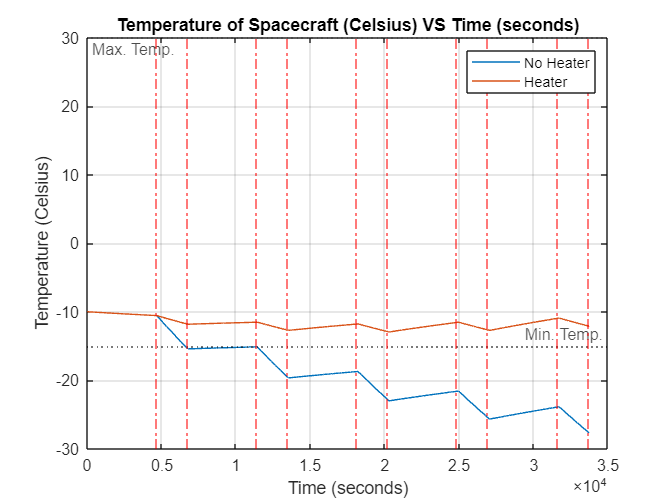

    elseif orbit_time >= period
        orbit_time = 0; % Orbit period reset
    end
end

### Task 6 - Plotting Temperature VS Time

To plot temperature against time, I converted the temperature array entirely to celsius, then for the plot itself, I enabled major grid lines to enhance readability, and labelled the axes, the graph and showed eclipse periods through the use of a for loop which finds the beginning and end of each of these eclipse periods. 

figure;
plot(time_elapsed, temperature-273.15);
hold on;
plot(time_elapsed, temperature_heater-273.15);
L = legend ('No Heater', 'Heater', 'Location', 'northeast'); % Legend and its positioning
L.AutoUpdate = 'off'; % Prevents the automatic labelling of the lines to show eclipse period
yline(-15, 'k:', 'Min. Temp.'); % Plots a line to show minimum temperature at -15 degrees celsius
yline(30, 'k:', 'Max. Temp.', ... % Plots a line to show maximum temperature at 30 degrees celsius
    'LabelVerticalAlignment', 'bottom', 'LabelHorizontalAlignment', 'left'); % Label positioning
grid on;

Giving the graph a title and labelling the x-axis and y-axis. 

xlabel('Time (seconds)');
ylabel('Temperature (Celsius)');
title('Temperature of Spacecraft (Celsius) VS Time (seconds)');

This segment of code plots vertical lines at the start and end of the eclipse period for however many periods are required, which, in this case, is 5. 

for i = 1:sim_iterations
    xline(i*period-eclipse_time,'r-.'); % Plots line at the beginning of an eclipse
    xline(i*period, 'r-.'); % Plots line at the beginning of an eclipse
end

### Discussion

With the given values of absorptivity and emissivity and no heater, the spacecraft dips below the minimum temperature in just 2 orbital periods. For this reason, I chose to add a heater as absorptivity or emissivity values are difficult to change for a spacecraft that already has its materials decided. If we were to add foils or coverings, this would change the mass and it would make it more difficult to find the exact position of the centre of mass. On the other hand, the heater is a small, lightweight part that can also be controlled if needed. 

Through trial and error, I have decided on the power of the heater to be 3000W, which allows for the spacecraft to remain above minimum temperature at all times, preventing any damage or general inoperability of any parts. 

To demonstrate the long-term feasability of this heater, I have recalculated the previous simulation but changing the simulation time to 100 orbits. 

This piece of code is identical to the one previously described, aside from the simulation iteration, which has been changed to 100 from 5 so that the simulation runs through 100 orbits. The only other difference is that there are no verical lines showing eclipse periods. I have removed this because it is far to resource intensive as it extends the length of time that the program takes to run and the vertical lines are functionally meaningless if there are 200 of them. 

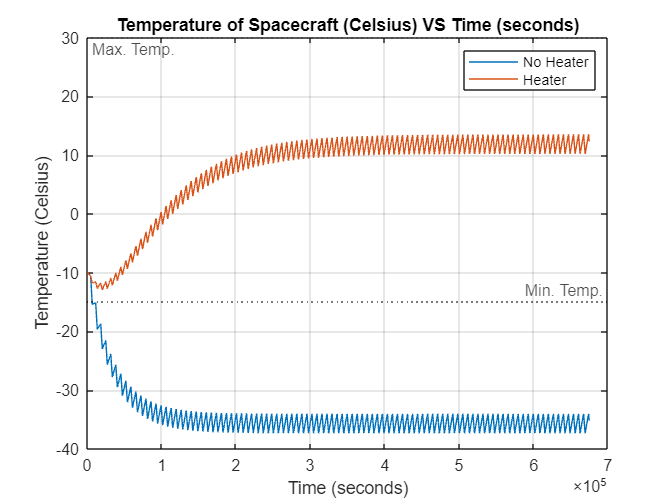

sim_iterations = 100; % Number of orbits the simulation will run through
P = period*sim_iterations; % [s] Total simulation time
simulation_time = 0; % [s] Current simulation time
orbit_time = 0; % [s] Current orbit time
time_elapsed(1) = 0; % [s] Array of time spent in the simulation to be plotted against temperature
temperature(1) = T_initial; % [K] Array for temperature with heater off to be plotted against time
temperature_heater(1) = T_initial; % [K] Array for temperature with heater on to be plotted against time
T = T_initial; % [K] Current temperature without heater
T_heater = T_initial; % [K] Current temperature with heater

dt = period/500; % [s] Time step
step_counter = 1; % Iteration counter

while simulation_time < P
    step_counter = step_counter + 1;
    time_elapsed(step_counter) = time_elapsed(step_counter-1) + dt;
    temperature(step_counter) = T;
    temperature_heater(step_counter) = T_heater;
    if orbit_time < sun_time
        orbit_time = orbit_time + dt;
        simulation_time = simulation_time + dt;
        dT = dt*(eq_temp_high^4 - T^4)/thermal_time_constant; % [K] Temperature change using high equilibrium temperature
        T = T + dT; % [K] New temperature for the spacecraft without the heater
        T_heater = T_heater + dT; % [K] New temperature for the spacecraft with the heater
    elseif orbit_time >= sun_time && orbit_time < period
        orbit_time = orbit_time + dt;
        simulation_time = simulation_time + dt;
        dT = dt*(eq_temp_low^4 - T^4)/thermal_time_constant; % [K] Temperature change for unheated spacecraft
        dT_heater = dt*(eq_temp_heater^4 - T_heater^4)/thermal_time_constant; % [K] Temperature change for heated spacecraft
        T = T + dT; % [K] New temperature for the spacecraft without the heater
        T_heater = T_heater + dT_heater; % [K] New temperature for the spacecraft with the heater
    elseif orbit_time >= period
        orbit_time = 0; % Orbit period reset
    end
end
figure;
plot(time_elapsed, temperature-273.15);
hold on;
plot(time_elapsed, temperature_heater-273.15);
L = legend ('No Heater', 'Heater', 'Location', 'northeast'); % Legend and its positioning
L.AutoUpdate = 'off'; % Prevents the automatic labelling of the lines to show eclipse period
yline(-15, 'k:', 'Min. Temp.'); % Plots a line to show minimum temperature at -15 degrees celsius
yline(30, 'k:', 'Max. Temp.', ... % Plots a line to show maximum temperature at 30 degrees celsius
    'LabelVerticalAlignment', 'bottom', 'LabelHorizontalAlignment', 'left'); % Label positioning
grid on;
xlabel('Time (seconds)');
ylabel('Temperature (Celsius)');
title('Temperature of Spacecraft (Celsius) VS Time (seconds)');

The plot shows that, over 100 periods, both temperatures begin to plateau, so we can assume that the temperatures at which they find themselves will be constant for the rest of the spacecraft's lifecycle. Clearly, the spacecraft with no heater plateaus under the minimum operating temperature of -15 degrees celsius, which means that some or all the components on the spacecraft will be out of use. 

The most likely reason for this minimum temperature is batteries. Oftentimes, the batteries on a spacecraft have the smallest operating temperature range, meaning that if the temperature of the spacecraft overall drops below their minimum temperature, they will stop working altogether. If the batteries stop working altogether, there is no way for the spacecraft to be powered in an eclipse, assuming that it doesn't have fuel cells. This means that the ground station would essentially 'lose' the spacecraft for a part of every period, and once the spacecraft is powered by photovoltaics again, it would have to turn back on and autonomously point towards the ground station. 

Turning off a spacecraft at all is always a risk as there is no guarantee that it will be possible to turn it back on, so having to turn the spacecraft on several times a day would be entirely unsustainable and the mission would likely be ended extremely prematurely. 

The spacecraft with its heater turned on during eclipse periods remains above the minimum operating temperature at all times and approaches but does not come considerably close to exceeding the maximum operating temperature. The high equilibrium temperature seems to be in the region of 10-15 degrees celsius, which may be slightly too close to the maximum operating temperature. If the heater could adjust how much power it is providing to the spacecraft, then it could provide the full 3000w in the first few orbits to prevent the temperature dropping below -15 and then decrease the power output to roughly 2000W in order to prevent overheating. 

# Tutorial 3 - Communications Link Budget Analysis

## Introduction

These tasks cover tutorial 3, which aims to deduce which of three given antennas with given properties is most well suited for the mission objective. The antenna needs to be operational at an altitude of 1336km with enough Link Margin to be able to communicate with the ground station and the ability to operate in the necessary frequency range of the ground station. Once these base requirements have been met, the antenna should, if possible, be optimised for minimum mass and noise temperature, and maximum beamwidth, so that it has the least influence on the spacecraft's dry mass, and therefore delta-v, and it can provide the clearest signal possible even if the antenna is not pointed perfectly towards the groundstation. This will mean that the attitude determination and control system will have to do much less work to constantly correct and perfectly point the spacecraft in the ideal direction to be able to receive and send data or instructions to or from the ground. 

### Task 1 - Identify Receiving and Transmitting Stations

The receiving element is the ground station and the transmitting element is the space segment because of the presence of 'Downlink Frequency', which indicates that data is being sent down from the space segment to the ground station. 

### Task 2 - Define Constants

For terms relating to the ground station, I have used 'gs' as a suffix, whereas if the term relates to the space segment, I have used 'ss'. 

For example, the Transmission Power of the ground station is given as P_Tgs, and the transmission power of an antenna in the space segment is given as P_Tss. 

#### Details of the communications link ground station:

P_Tgs = 35;                                 % [W] Transmission Power
T_Rgs = 257;                                % [K] Noise Temperature
D_gs = 4.5;                                 % [m] Antenna Diameter

#### Details of the communications link space segment:

For the space segment, I have created an array for each property, where the first index represents the values for the parabolic antenna, the second is for helix antenna, and the third index is for the horn antenna. This is useful as I will be using matrix multiplication later on, and it is a significantly shorter way of writing out all the constants. 

% antenna_property = [parabolic value, helix value, horn value];
P_Tss = [30, 90, 54];                       % [W] Transmission Power For Each Antenna
T_Rss = [156, 160, 170];                    % [K] Noise Temperature For Each Antenna
theta_bw = [35, 30, 33];                    % [deg] Antenna Beamwidth For Each Antenna
ss_mass = [30, 12, 2];                      % [kg] Mass For Each Antenna

#### Details of the platform communications link parameters:

BER = 8 * 10^(-6);                          % Bit Error Rate
R_b = 150;                                  % [Mbps] Transmission Rate
f_d = 8.9;                                  % [GHz] Downlink Frequency
L_i = 1.85;                                 % [dB] Implementation Losses
L_add = 7;                                  % [dB] Additional Losses
k = 1.38 * 10^(-23);                        % [JK^-1] Boltzmann Constant

### Task 3 - Identify and Rearrange Correct Gain Equations For Each Antenna

Each antenna has different equations for their respective gains, so it will be necessary to collect and rearrange each equation to find these values. 

#### Gain for the Parabolic Antenna

The empirical formula for gain for a parabolic antenna is given as:

Equation (8.20)

#### $G=17\ldotp 8+20\log \left(D\right)+20\log \left(f\right)$,

which is not useful yet since we do not know the frequency *f* or the antenna diameter *D*, however, we can combine the log terms to yield $20\log \left(f*D\right)$, and rearrange the following formula to make *f*D* the subject since we have *θ*:

Equation (8.19)

$\theta =\frac{21}{\left(f\right)\left(D\right)}$,

where $\theta$ is the antenna beamwidth, *f* is frequency, and *D* is the parabolic antenna's diameter. 


$$\left(f*D\right)=\frac{21}{\theta }$$


Therefore, the gain equation for a parabolic antenna turns into: 


$$G=17\ldotp 8+20\log \left(\frac{21}{\theta }\right)$$


#### Gain for the Helix Antenna

A similar approach is required for finding the gain of the Helix antenna with the information we are given. The main formula for gain for a helix antenna is: 

Equation (8.18)

#### $G=10\ldotp 3+10\log \left(\frac{\pi^2 D^2 L}{\lambda^3 }\right)$,

and the equation that we can rearrange is: 

Equation (8.17)

$\theta =\frac{52}{\sqrt{\frac{\pi^2 D^2 L}{\lambda^3 }}}$,

which, once rearranged, gives: 


$$\frac{\pi^2 D^2 L}{\lambda^3 }=\frac{{52}^2 }{\theta^2 }$$


Substituting the above equation into the intial gain equation: 


$$G=10\ldotp 3+20\log \left(\frac{52}{\theta }\right)$$


#### Gain for the Horn Antenna

Once again, the method for finding the gain of a horn antenna is similar to the previous two, where the initial gain formula is given as: 

Equation (8.16)

#### $G=20\log \left(\frac{\pi D}{\lambda }\right)-2\ldotp 8$,

and the *θ* formula to rearrange is:

Equation (8.15)

$\theta =\frac{255\lambda }{\pi D}\longrightarrow \frac{\pi D}{\lambda }=\frac{255}{\theta }$,

and the final equation for gain is:


$$G=20\log \left(\frac{255}{\theta }\right)-2\ldotp 8$$


### Task 4 - Calculate Gain For Each Antenna

Now that the individual antenna gain equations have been found, they must be calculated and stored into an array, which I have named 'antenna_gain'. For clarity, I have also made variables for each position in the array that are the gains for their respective antennas. 

#### Gain calculation for each antenna:

To calculate the gain of the antenna's we simply substitute in the known values for θ for each antenna. 

#### Parabolic antenna

Below is the equation for gain for the parabolic antenna, substituting in the value of θ = 35 [deg], which is given at the start of the tutorial as a constant. 


$$G=17\ldotp 8+20\log \left(\frac{21}{35}\right)=17\ldotp 8+-4\ldotp 437=13\ldotp 363\;\textrm{dB}$$


G_para = 17 + 20*log10(21/theta_bw(1)); % [dB] Parabolic Antenna Gain

#### Helix antenna

The helix antenna's antenna beamwidth θ = 30 [deg], and the equation is shown below. 


$$G=10\ldotp 3+20\log \left(\frac{52}{30}\right)=10\ldotp 3+4\ldotp 778=15\ldotp 078\;\textrm{dB}$$


G_heli = 10.3 + 20*log10(52/theta_bw(2)); % [dB] Helix Antenna Gain

#### Horn antenna

The horn antenna's antenna beamwidth θ = 33 [deg], and the equation is shown below. 


$$G=20\log \left(\frac{255}{33}\right)-2\ldotp 8=17\ldotp 761-2\ldotp 8=14\ldotp 961\;\textrm{dB}$$


G_horn = 20*log10(255/theta_bw(3))-2.8; % [dB] Horn Antenna Gain

Now that the antenna's individual gains have been calculated, they must be established in an array. 

antenna_gain = [G_para, G_heli, G_horn]; % [dB, dB, dB] Antenna Gains

### Task 5 - Calculate Effective Isotropic Radiator Power For Each Antenna

Once the antenna gain array has been established, we can calculate the Effective Isotropic Radiator Power (EIRP) of each antenna and establish those values in an array as well. 

The EIRP depends on gain $G_T$, and power $P_T$, and the equation is shown below:

Equation (8.10)

#### 
$$G_T *P_T =\textrm{EIRP}$$


Now, to calculate each EIRP using the antenna gain array and establish the EIRP array. Before this, however, the transmitted power *P_Tss* must be converted into decibel watts [dBW] to be able to add it to the antenna gain and receive *EIRP*.  

P_Tss_dBW = 10*log10(P_Tss); % [W]
EIRP = antenna_gain + P_Tss_dBW; % [dBW]

### Task 6 - Calculate Receiving Station Gain

To calculate the gain of the receiveing ground station, the correct equation to use is the same as the one used in the calculation of gain for the spacecraft's parabolic antenna because the receiving ground station is a parabolic antenna as well: 

Equation (8.20)


$$G=17\ldotp 8+20\log \left(D\right)+20\log \left(f\right)$$


However, in this case, since we have the antenna diameter and frequency, we can simply use the original equation instead of transforming it to find in terms of θ. Downlink frequency *f=8.9 [GHz]*, and antenna diameter *D = 4.5 [m]. *Additionally, there is no need to convert to Hz from GHz because the equation given required frequency in GHz already. 

$G=17\ldotp 8+20\log \left(4\ldotp 5\right)+20\log \left(8\ldotp 9\right)$;

G_gs = 17.8 + 20*log10(D_gs) + 20*log10(f_d); % [dB]

### Task 7 - Calculate Gain to Noise Density Ratio

To find the gain-to-noise density ratio, we have to first find the noise. 

Equation (8.22)

#### 
$$N_0 =10\log_{10} \left(k\right)+10\log_{10} \left(T_R \right)$$



$$N_0 =10\log_{10} \left(1\ldotp 38*{10}^{-23} \right)+10\log_{10} \left(257\right)$$



$$N_0 =-204\ldotp 5\;{\textrm{dBWHz}}^{-1}$$


noise_gs = 10*log10(k) + 10*log10(T_Rgs); % [dBWHz^-1] Ground Station Noise

Now, we simply subtract the noise of the ground station from the calculated gain for the ground station to find the gain-to-noise density ratio as they are both already in decibel form:

Equation (8.25)

#### 
$$\textrm{GRN0R}=10\log_{10} \left(\frac{G_{\textrm{gs}} }{N_0 }\right)$$



$$\textrm{GRN0R}=G_{\textrm{gs}} -N_0$$



$$\textrm{GRN0R}=49\ldotp 85-\left(-204\ldotp 5\right)$$



$$\textrm{GRN0R}=254\ldotp 35\;\textrm{dBW}\;{\textrm{Hz}}^{-1}$$


GRN0R = G_gs - noise_gs; % [dBWHz^-1] Gain-to-noise density ratio

### Task 8 - Create Altitude and Slant Range Arrays

Free space loss (FSL) calculation requires the declaration of an array of altitude ranges that start at the given minimum altitude of 250km and that go up to the maximum given altitude of 2500km. 

alt_range = linspace(250, 2500, 500); % [km] Altitude array from 250km to 2500km

This array is used to gather a range of link margins on a range of altitudes so that we can decide which antenna will be most effective. 

The next step is to calculate the slant range *S, *which is calculated for each altitude, and for this tutorial, we are considering the worst case scenario, where we assume the spacecraft is being viewed from a ground station at its furthest visible point, which is on the horizon. The equation for slant range is provided below, and for each calculation that uses a range, I will show the minimum and maximum values in the array in question: 

$S=\sqrt{{\left(R_e +h\right)}^2 -R_e^2 }$,

where R_e is the earth's radius and h is the orbital altitude


$$S_1 =\sqrt{{\left(6371+250\right)}^2 -{6371}^2 }=1\ldotp 80*{10}^3 \;m$$



$$S_{500} =\sqrt{{\left(6371+2500\right)}^2 -{6371}^2 }=6\ldotp 17*{10}^3 \;m$$


slant_range = sqrt((R_earth+alt_range).^2-6371^2);

We also have to calculate the wavelength of the transmitted signal, which is found by using the same equation that relates velocity, frequency, and wavelength for any wave of light. 


$$\lambda =\frac{v}{f}$$



$$\lambda =\frac{3*{10}^8 }{f_d }=\frac{3*{10}^8 }{8\ldotp 9*{10}^9 }$$



$$\lambda =0\ldotp 0337\;m$$


lambda = (3*10^8)/(f_d*10^9); % [m] Wavelength

### Task 9 - Calculate Free Space Loss

Calculating FSL using the previously calculated variables. 

FSL equation is given as: 

Equation (8.30)

#### 
$$L_{\textrm{fs}} =10\log_{10} {\left(\frac{4\pi S}{\lambda }\right)}^2$$



$$L_{\textrm{fs}} =20\log_{10} \left(\frac{4\pi S}{\lambda }\right)$$


where λ is the wavelength of the signal, and S is the slant range. 


$$L_{\textrm{fs1}} =20\log_{10} \left(\frac{4\pi *1800*{10}^3 }{0\ldotp 0337}\right)$$



$$L_{\textrm{fs1}} =176\ldotp 5\;\textrm{dB}$$



$$L_{\textrm{fs500}} =20\log_{10} \left(\frac{4\pi *6170*{10}^3 }{0\ldotp 0337}\right)$$



$$L_{\textrm{fs500}} =187\ldotp 2\;\textrm{dB}$$


L_fs_dB = 20*log10(4*pi*slant_range.*10^3/lambda); % [dB] Free Space Loss

### Task 10 - Calculate Carrier to Noise Density Ratio

Now, to calculate Carrier to Noise Density Ratio (CN0R), the equation is once again simple addition as everything has already been worked out in decibel form: 

Equation (8.33)

#### 
$$\textrm{CN0R}=\textrm{EIRP}+\textrm{GRN0R}-L_{\textrm{fs}} -L_{\textrm{add}}$$


However, EIRP is different for each antenna and FSL is a 1x500 array so CN0R is being calculated foe each antenna at each altitude, so I have created a 2D, 500x3 array for CN0R, where the first index represents the value of CN0R at one of 500 altitudes, and the second index is the index that corresponds to each antenna type. 

#### Parabolic Antenna


$${\textrm{CN0R}}_{\textrm{parabolic1}} =27\ldotp 33+254\ldotp 35-176\ldotp 5-7$$



$${\textrm{CN0R}}_{\textrm{parabolic1}} =98\ldotp 14\;\textrm{dBHz}$$



$${\textrm{CN0R}}_{\textrm{parabolic500}} =27\ldotp 33+254\ldotp 35-187\ldotp 2-7$$



$${\textrm{CN0R}}_{\textrm{parabolic500}} =87\ldotp 45\;\textrm{dBHz}$$


#### Helix Antenna


$${\textrm{CN0R}}_{\textrm{helix1}} =34\ldotp 62+254\ldotp 35-176\ldotp 5-7$$



$${\textrm{CN0R}}_{\textrm{helix1}} =105\ldotp 43\;\textrm{dBHz}$$



$${\textrm{CN0R}}_{\textrm{helix500}} =27\ldotp 33+254\ldotp 35-187\ldotp 2-7$$



$${\textrm{CN0R}}_{\textrm{helix500}} =94\ldotp 73\;\textrm{dBHz}$$


#### Horn Antenna


$${\textrm{CN0R}}_{\textrm{horn1}} =32\ldotp 28+254\ldotp 35-176\ldotp 5-7$$



$${\textrm{CN0R}}_{\textrm{horn1}} =103\ldotp 09\;\textrm{dBHz}$$



$${\textrm{CN0R}}_{\textrm{horn500}} =27\ldotp 33+254\ldotp 35-187\ldotp 2-7$$



$${\textrm{CN0R}}_{\textrm{horn500}} =92\ldotp 40\;\textrm{dBHz}$$


for i = 1:3
    CN0R(:, i) = EIRP(i) + GRN0R - L_fs_dB - L_add; % Carrier to Noise Density Ratio [dBHz]

### Task 11 - Calculate Energy per Bit to Noise Density Ratio

The same 500x3 array method is used for calculating EBN0, and an example calculation for each antenna is shown below: 

The initial equation for EBN0 is:

Equation (8.25)

$\textrm{EBN0}=\textrm{CN0R}-10\log_{10} \left(R_b *{10}^6 \right)$,

where R_b is transmission rate [Mbps]

#### Parabolic Antenna


$${\textrm{EBN0}}_{\textrm{parabolic1}} =98\ldotp 14-10\log_{10} \left(150*{10}^6 \right)$$



$${\textrm{ENB0}}_{\textrm{parabolic1}} =16\ldotp 38\;\textrm{dB}$$


#### Helix Antenna


$${\textrm{EBN0}}_{\textrm{helix1}} =105\ldotp 43-10\log_{10} \left(150*{10}^6 \right)$$



$${\textrm{ENB0}}_{\textrm{helix1}} =23\ldotp 67\;\textrm{dB}$$


#### Horn Antenna


$${\textrm{EBN0}}_{\textrm{horn1}} =103\ldotp 09-10\log_{10} \left(150*{10}^6 \right)$$



$${\textrm{EBN0}}_{\textrm{horn1}} =21\ldotp 33\;\textrm{dB}$$


In the code itself, this operation is obviously much quicker because it is creating the array as it finds the values. 

    EBN0(:, i) = CN0R(:, i) - 10*log10(R_b * 10^6); % Energy per bit-to-noise density ratio [dB]
end

### Task 12 - Calculate Probability of Error

Now for link quality requirements, we must first find the probability that a single bit is erroneous, which, for  Differnetial Phase Shift Keying (DPSK) modulation technology, is given by the following equation: 


$$P_e =\frac{1}{2}e^{-{10}^{\left({\frac{E_b }{N_0 }}_{\textrm{BER},\;\textrm{est}} *\frac{1}{10}\right)} }$$


In this equation, ${\frac{E_b }{N_0 }}_{\textrm{BER},\;\textrm{est}}$ represents an array which contains a range of possible values of EBN0 that still meet performance requirements. The array is established below: 

EBN0_est = linspace(0, 15); % [dB]
P_e = 0.5*exp(-10.^((EBN0_est)./10)); % Probability of Error

### Task 13 - Find Appropriate EBN0 Value to Best Match the Bit Error Rate

Now to find the best EBN0 value for the satellite's required Bit Error Rate (BER), we use the given interp1 function. 

EBN0_best = interp1(P_e, EBN0_est, BER); % [dB]

### Task 14 - Calculate Link Margin For Each Antenna

The final link margin calculation uses the results from Task 11 and Task 13: 


$$\textrm{Link}\;\textrm{Margin}=\textrm{EBN0}-{\textrm{ENB0}}_{\textrm{best}} -L_i$$


This operation will have to be carried out with a for loop to create a 500x3 2D array to find the link margin for each available antenna across slant ranges. 

link_margin = EBN0 - EBN0_best - L_i;

### Task 15 - Plot Resultant Link Margin VS Altitude

Now to plot the link margins for each antenna against each other across slant ranges. 

for j = 1:500
    if link_margin(j, 3) <=0.006 && link_margin(j, 3) >= -0.006
        max_horn_altitude = alt_range(j);
    end
end

The above piece of code calculates the maximum altitude at which the horn stops being able to transmit to the ground station, which will be talked about further in the discussion. 

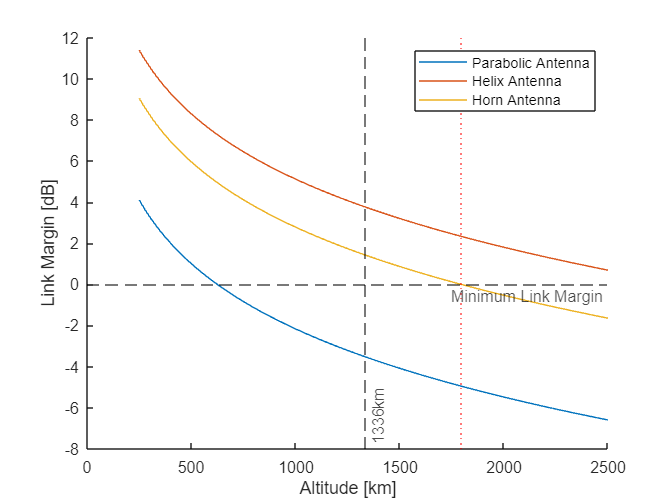

figure;
hold on;

plot(alt_range, link_margin);
xline(max_horn_altitude, 'r:');
ylabel('Link Margin [dB]');
xlabel('Altitude [km]');
xline(1336, 'k--', '1336km', 'LabelVerticalAlignment', 'bottom');
yline(0, 'k--', 'Minimum Link Margin', 'LabelVerticalAlignment', 'bottom');
legend('Parabolic Antenna', 'Helix Antenna', 'Horn Antenna');

## Discussion

- Given the chosen altitude of 1336km, only the horn antenna or the helix antenna would be suitable as the parabolic antenna has a negative link margin at 1336km altitude, meaning that it would not have enough gain to communicate with the ground station for this particular mission. 

- The parabolic antenna is not usable due to the negative link margin at the required altitude. The helix antenna, despite being above the link margin for all altitudes up to 2500km, would not be able to communicate with the receiving ground station because of its frequency range. Helix antennas operate between 300MHz and 3GHz, which is below the required downlink frequency of 8.9GHz. I would propose the horn antenna because it is the only antenna that can communicate with the ground station based on its frequency range (300MHz - 30GHz) and positive link margin at the required altitude. The horn antenna has the additional benefits of being 10kg lighter than the helix antenna as well as having 3 degrees extra of antenna beamwidth. On the other hand, it has lower transmission power, and higher noise temperature than the helix antenna, as well as having a limit to its altitude as it does not have sufficient link margin to communicate with the ground station beyond a certain altitude (roughly 1800km). 

- If I could adjust any part of either the space or ground segment by a factor of 2, I would double the ground station's antenna diameter to provide additional gain and therefore additional link margin to the mission. This would not increase the mass of the spacecraft itself, and might actually decrease the size of antenna required, thereby decreasing dry mass, increasing possible change in velocity given the same mass of fuel, which could then mean that less fuel is required for the same mission specification. This would save cost and complexity from the mission as well as perhaps allowing it to be a passenger on a rideshare mission, meaning that launch price would decrease considerably. On the other hand, it may delay the launch date as the ground station antenna needs to be upgraded so considerably, but the most likely outcome is that the mission would switch to a different antenna altogether, meaning that there would not be any effect on launch date. 

# Tutorial 4 - Attitude Determination and Control Systems

## **Introduction**

In this tutorial, I will make use of integration, separate function, and the **area** plot in MATLAB to calculate the magnitudes of gravity and drag torque and three different altitudes to analyse which altitude is best and how much momentum store the on-board reaction wheels will have to have in order to successfully carry out the Sentinel 6B mission. 

This mission design process requires specific attention being paid towards the Attitude Determination and Control System (ADCS) in order to be able to carry out crucial tasks that are essential to the success of the mission. Without proper or sufficient momentum storage, the spacecraft might be unable to point towards the correct location to conduct science experiments or communicate with the ground station. Alternatively, if the reaction wheels are too powerful, this adds unnecessary mass to the system, meaning that more fuel will be required, increasing mass again and driving costs of manufacturing and cost up. 

Therefore, it is absolutely critical to be able to determine what the best reaction wheel for the job is, and this can only be accomplished through careful analysis of the properties of the spacecraft itself. 

### **Task 1 - Defining Inputs**

Most of the inputs that are being defined in this task are given, however orbital velocity at each altitude will have to be calculated. Additionally, I have not created any array with three indices, as this can be done automatically later on. Instead, I have just declared two empty arrays, one for gravity torque and one for drag torque, both of which will be filled later on with the appropriate values. I have done this to be able to define the gravity and drag torque alongside all other inputs that will be required throughout the tutorial, but these empty arrays don't hold any practical value to the execution of the code. 

altitudes = [1000000, 1336000, 2000000];                % [m] Altitude array
T_g = [];                                               % torque due to gravity array
T_D = [];                                               % torque due to atmospheric drag array
I_yy = 25; I_zz = 40;                                   % [kgm^-2] Mass moments of inertia
C_d = 2.2;                                              % [] Coefficient of drag
rho_alts = [3*10^-15, 8.5*10^-16, 7*10^-17];            % [kgm^-3] Densities at various altitudes
mu = 3.986*10^14;                                       % [m^3s^-2] Redefined gravitational parameter in metres
R_earth = 6371000;                                      % [m] Redefined earth radius in metres

Calculating orbital velocity simply requires using the equation found in the coursenotes. 

Equation (3.8)

#### 
$$v=\sqrt{\frac{\mu }{r}}$$


Gravitational parameter $\mu$

    
$$\mu =3\ldotp 986*{10}^{14} m^3 s^{-2}$$


Orbital radius $r$

    
$$\begin{array}{l}
r=R_{\textrm{earth}} +\textrm{altitude}\\
r=6371+\left\lbrack 1000,1336,2000\right\rbrack =\left\lbrack 7371,7707,8371\right\rbrack *{10}^3 m
\end{array}$$


Orbital velocity $v$


$$v=\sqrt{\frac{3\ldotp 986*{10}^{14} }{\left\lbrack 7371,7707,8371\right\rbrack *{10}^3 }}=\left\lbrack 7354,7192,6901\right\rbrack *{10}^3 {\textrm{ms}}^{-1}$$


vel_alts = [sqrt(mu./(R_earth+altitudes))];             % [ms^-1] Velocity array at each altitude

Sentinel 6A satellite did not have any extendable solar panels, and the surface area of this satellite is only roughly 20m^2, so it is clear that this is not a particularly large satellite with excessively sized surfaces of low mass. Therefore, it is valid to assume that the centre of mass is not very far from the centre of pressure. For this reason, I made an educated guess that they are 50cm apart.  

CgToCp = 0.5;                                           % [m] Distance between centre of mass and centre of pressure

### Task 2 - Find Gravity Torque

In tasks 3, 4, and 5, I have explained the function I use here to find a value for gravity torque. The function uses array multiplication to eliminate the need of a for loop, meaning that with one operation, all values in the **altitudes** array create an equally sized gravity torque array. 

Equation (9.6): 


$$T_{\textrm{Qg}} =\left(\frac{3\mu }{2R^3 }\right)\left|I_{\textrm{ZZ}} -I_{\textrm{YY}} \right|\sin \left(2\theta \right)$$


θ is the angle between the spacecraft's Z-axis and the local vertical axis.

For this analyis, I will assume the worst case scenario, which is when θ is 45 degrees, making sin(2θ) = 1, meaning that the torque due to gravity will be as large as it can be as the sin function does not exceed 1.  

### Task 3-7 are discussed at the bottom of the livescript

### Task 8 - Get Maximum Gravity and Drag Torques

To find the largest values of the torques, both due to gravity and due to air resistance, we simply equate the variable for maximum torque to their respective function outputs. Once again, there is no need for a loop as the functions themselves allow their outputs to be arrays. 

T_g = get_T_g(I_zz, I_yy, altitudes, mu, R_earth);
T_D = get_T_D(rho_alts, C_d, area_surface, vel_alts, CgToCp);

### Task 9 - Calculate Orbital Period

To calculate orbital period, I used the equation found in the course notes. 

$\tau =2\pi \sqrt{\frac{r^3 }{\mu }}$    (3.9)

This equation is for circular orbits, which is a valid assumption as any changes to apogee or perigee due to atmospheric drag will be negligible. 


$$\begin{array}{l}
\tau_{1000} =2\pi \sqrt{\frac{{\left(6371+1000\right)}^3 }{398600}}=6298\;\textrm{seconds}\\
\tau_{1336} =2\pi \sqrt{\frac{{\left(6371+1336\right)}^3 }{398600}}=6734\;\textrm{seconds}\\
\tau_{2000} =2\pi \sqrt{\frac{{\left(6371+2000\right)}^3 }{398600}}=7622\;\textrm{seconds}
\end{array}$$


This operation will be carried out using array multiplication and the period of each orbit will be stored in an array where the index corresponds to the index in the altitude array, so the first value in the orbital period array will be the period for the altitude found in the first index of the altitude array. 

periods = 2.*pi.*sqrt((R_earth+altitudes).^3./mu); % [s] Array of orbital periods

### Task 10 - Create Function for Total Torque

Now to calculate the change of torque over a period, we know that the torque due to gravity will change depending on the spacecraft's current orbital position, and since the orbital location is a function of time, we can relate the max value of torque due to gravity that was found and multiply it by the sinusoidal function of time. 

Torque due to atmospheric drag, on the other hand, is constant throughout the orbit. 

The following equation finds total torque at a point in the orbit and is given in the tutorial. 


$$f\left(t\right)=\cos \left(\frac{t}{\tau }2\pi \right)*T_G +T_D$$


Where t is the time variable representing time elapsed in the orbit, $\tau$ is the previously calculated orbital period, $T_G$ is the maximum value of torque due to gravity, and $T_D$ is the maximum value of torque due to air resistance. 

Inspecting this equation reveals that maximum total torque will occur when the cos term is equal to 1, which is when $\frac{t}{\tau }=0$ or any multiple of 2π. Therefore, the maximum value of torque occurs at the beginning of every orbit, where $t=0$. 

On the other hand minimum torque value occurs when $\frac{t}{\tau }=\frac{1}{2}$ as it means that the cos term will be -1. Therefore, the minimum torque value will occur halfway through every period. This means that the only component of torque affecting the spacecraft is atmospheric drag, which would happen whenever the spacecraft's axis for mass moment of inertia is aligned with the local vertical. 

I will run a for loop to find the total torque over a period for each given altitude, using the torque values for each altitude as well. The loop will run once for each altitude. 

Required momentum store for 1000km is 0.0018825 kgm^2s^-1


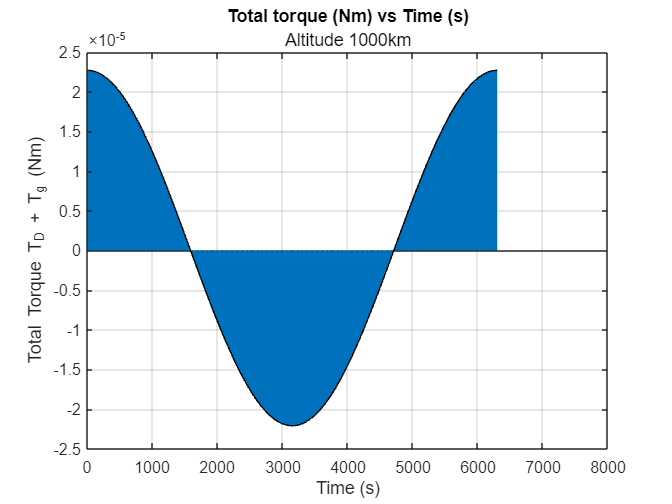

Required momentum store for 1336km is 0.0005454 kgm^2s^-1


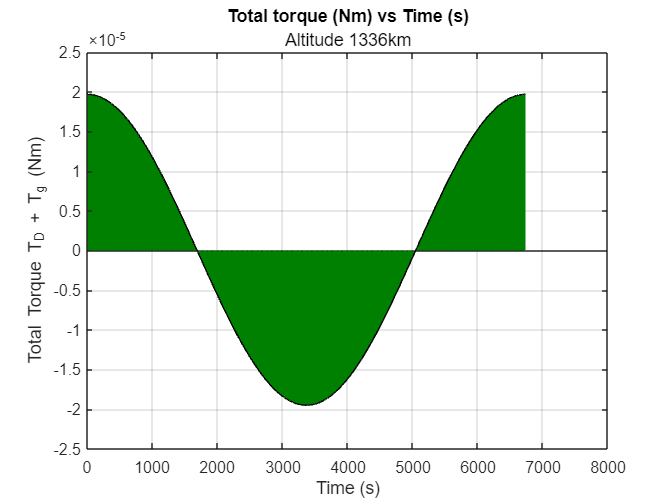

Required momentum store for 2000km is 4.681e-05 kgm^2s^-1


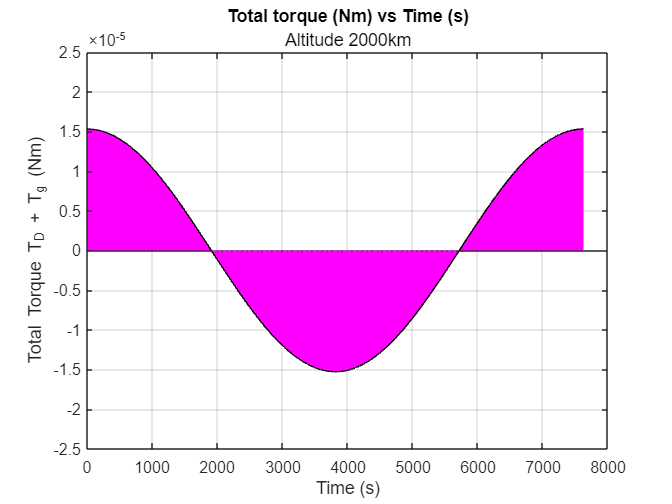

for i = 1:length(altitudes)

Firstly, I store the current orbit's values for maximum gravity and drag torque to make algebraic equation manipulation more simple and readable. 

    max_T_g = T_g(i);
    max_T_D = T_D(i);

Now, I create a function for total torque, which will then be integrated to find momentum store required for the current orbit. This function is also saved as an array, which allows me to have one term for whcih can store all functions for total torque instead of creating one function for each altitude. This function is simply the same as the one shown above, which I have copied again below and renamed to match the code: 


$$T_{\textrm{total}} \left(t\right)=\cos \left(\frac{t}{\tau }2\pi \right)*T_G +T_D$$


    T_total{i} = @(t) cos(t*2*pi/periods(i))*(max_T_g) + max_T_D; % [kgm^2s^-2]

I save the value of the current orbit's period to use later on when calculating the actual values of total torque required, which will then be plotted against time. 

    simulation_time = periods(i); % [s] Period of current orbit

### Task 11 - Calculate Momentum Storage Required

The momentum store required is calculated at the start of each simulation for each orbital altitude through the use of the built-in **integral** function, with the integrand being the previously calculated function for total torque. 


$$H_{\textrm{required}} =\int_0^{\tau \;} T_{\textrm{total}} \left(t\right)\;\textrm{dt}$$


This momentum store value is also an array which stores the value of momentum store for each altitude in the same term, simplifying the code. 

    H_required{i} = integral(T_total{i}, 0, periods(i)); %[kgm^2s^-1] Momentum storage required for each altitude

I have had to save the output as an object in MATLAB as the **disp** function does not allow function arrays like the one I have created for momentum store, but then the object is used as the argument for the **disp** function, which can then be outputted at the top of the momentum store's respective graph. 

    output = ['Required momentum store for ', num2str(altitudes(i)/1000), '' ... % output divided for readability
        'km is ', num2str(H_required{i}), ' kgm^2s^-1']; % output saved to an object
    disp(output);

### Task 12 - Find Value of Total Torque for Each Period

To be able to plot total torque over a period, I must create a 2D array that stores the torque value across one orbit for each altitude, with the time step being one second. 

    for t = 1:simulation_time

This loop runs through every second of each altitude's period, and stores the total torque value to then be plotted on an **area** plot. This means that it is very precise measurement, and it is most likely that in the real mission, this level of precision would not necessarily be required, and measurements could be taken every 10 seconds to conserve power. 

        T_total_values(t, i) = cos(t*2*pi/periods(i))*(max_T_g) + max_T_D;

Now that torque values have been calculated, I end the for loop that was used to find the values themselves but the loop for finding momentum store continues for the remaining orbits, which then means that the other two orbits also have their total torque values calculated. 

    end
    figure;

### Task 13 - Plot Results Using 'area'

Now, to plot each graph and show the area under each graph, which results in the sum of all momentum change in the orbit I have used the **area** function, which is a special kind of plot which shows the area under and above the curve up to the x-axis. 

The calculation of momentum store is problematic as the integral function will have subtracted the negative values of total torque from the positive ones, meaning that the value of momentum store that was found will have been an underestimation by roughly 33% as one third of the graph for an orbit is yielding negative torque values. I will account for this in the discussion, but the displayed values for momentum store required are slightly misleading. 

My use of the integral function assumes that the negative torque values essentially work to correct the torque on the spacecraft in the first part of the orbit, whereas in reality, the momentum store would need to account for the **magnitude** of each torque value, as even if the value is negative, the spacecraft must act against it to keep pointing in the correct direction. 

    area(1:simulation_time, T_total_values(:, i));

To be able to more easily compare each graph, I have standardised their ranges. This way, it is more clear to see the gradual decrease in momentum store required and increase in period. The highest altitude orbit at 2000km requires significantly less momentum store than the lowest altitude 1000km orbit because it is considerably further away from the atmosphere, so much so that the air density is orders of magnitude lower. Additionally, the higher altitude orbit is also less affected by the Earth's gravitational field strength, meaning that it suffers less from the effects of gravity torque. 

The combination of these two factors results in the obvious behaviour that the highest altitude has the longest orbit, the lowest maximum total torque and the lowest momentum store required. 

    ylim([-2.5*10^-5, 2.5*10^-5]);
    xlim([0 8000]);

Labelling the x and y axes. 

    ylabel('Total Torque T_D + T_g (Nm)');
    xlabel('Time (s)');

Plotting a horizontal line along $y=0$ using **yplot** makes the graph slightly more clear. I have also turned over major grid lines. 

    yline(0, ':');
    grid on;

I have made if statements to independently title each graph depending on its altitude as well as changing the colour of the shaded area using **colororder** to make the differences in each graph more clear. 

    if i == 1
        title('Total torque (Nm) vs Time (s)', 'Altitude 1000km');
    elseif i == 2
        colororder([0 0.5 0]);
        title('Total torque (Nm) vs Time (s)', 'Altitude 1336km');
    elseif i == 3
        colororder([1 0 1]);
        title('Total torque (Nm) vs Time (s)', 'Altitude 2000km');
    end
end

### Discussion

- If the centre of pressure was aligned in every axis with the centre of mass, there would never be any torque due to atmospheric drag, however this is a difficult problem to fix as the only way this would be possible is if the spacecraft was a sphere, such that any force acting on the spacecraft would be acting directly through the centre of mass at any orientation. A more practical solution would be to angle the spacecraft in such a way that the centre of pressure and the centre of mass are aligned in the direction of velocity. In this scenario, there would have to be constant adjustments made by the reaction wheels to very slowly turn the spacecraft as it travels along the orbit. For this to be possible, however, the reaction wheels would have to extremely precise and powerful enough, which would likely drive up component costs and mass, thereby increasing launch cost and fuel requirements. Additionally, there would have to be large redesigns of the structure of the spacecraft if a surface that is perfectly symmetrical in each axis does not exist on the spacecraft, and even if such a surface exists, it would have to be a surface that can point towards the velocity vector, which might not be possible if that surface already has sensitive equipment like antennas or science instruments that have to point in a certain direction. 

- If the centre of solar radiation pressure is aligned with the centre of mass, then the exclusion of this term is valid. It is unlikely that this is the case, however, so for a higher level analysis, it would be necessary to consider solar radiation pressure. Solar radiation pressure is generally quite small, particularly if there are no extendable solar arrays, which are usually the primary cause of significant disturbances due to this kind of pressure. Furthermore, solar radiation pressure is cyclic, meaning that any small effects that it does have on the spacecraft will likely be cancelled out by the start of the next orbit, assuming constant orientation to the earth, so there is likely very little need to consider its effects on the mass of fuel required. Magnetic field torque, on the other hand, I believe should be considered, particularly due to the inclination of the chosen orbit. The magentic field torque is most significant at the poles, being twice as effective than at the equator. The spacecraft is orbit at a 66 degree inclination, so not only will the poles have considerable disturbances on the total torque on the spacecraft, but it will also vary in intensity throughout an orbit. For this reason, I don't believe it is valid to neglect magnetic field torque from even a simple analysis. 

- Looking at the graph showing total torque for the mission's altitude of 1336km shows that the maximum torque is roughly $2*{10}^{-5} \;\textrm{Nm}$, requiring a momentum store of $0\ldotp 00055\;\textrm{Nms}$. As I mentioned previously, this momentum store is likely to be a 33% understimation, so I will assume that, with a 10% safety margin, the ADCS will require roughly $0\ldotp 000825\;\textrm{Nms}$. After applying the necessary filters of minimum torque and momentum store into https://www.satnow.com/search/reaction-wheels, there was only one reaction wheel available. This reaction wheel is the CW0017 CubeSpace Satellite Systems wheel with an available torque output of $2\ldotp 5*{10}^{-4} \;\textrm{Nm}$ and momentum store of $0\ldotp 00177\;\textrm{Nms}$. This reaction wheel requires up to 0.58W and as little as 0.15W and can operate between -20 and 80 degrees celsius. This makes it an excellent fit for the spacecraft as also only weighs 60 grams. 

# Tutorial 5 - Power and Mass Budget Analysis

## **Introduction**

In this final tutorial, I will conduct a power and mass budget analysis, calculating total masses and power requirements for the spacecraft's nominal operation. This tutorial is tightly linked with all previous tutorials, and once it is finished, it will dictate final values to provide to the launch team as this will decide crucial aspects of the launch such as ascent profile or launch windows. 

## **Initial Tasks**

**Define Constants**

R_earth = 6371000; % [m] Earth Radius
h = 1336000; % [m] Orbital altitude
mu = 3.986*10^14; % [m^3s^-2] Earth Gravitational Parameter
V_B = 18; % [V] Output voltage of the chosen satellite bus
recharge_cycles = 25000;
DOD = 50; % [%] Operational Depth of Discharge
energy_density = 120; % check for multiplication in other code
power_payload = 350; % [W]
power_thermal = 150; % [W]
power_heater = 2; % [W] - from Tutorial 2
power_comms = 240; % [W]
power_antenna = 54; % [W] - from Tutorial 3
power_ADCS = 110; % [W]
power_reaction_wheel = 0.58;
power_other = 150;

### Task 1 - Estimate Mission Lifetime

To find mission lifetime, we first have to calculate orbital period, which we can do using the equation found in the coursenotes. The battery will be mostly in use during the eclipse period, so we can use the calculation from tutorial 2 to find how much time the spacecraft spend in an eclipse over a period. 

Equation (3.9)

#### 
$$\tau =2\pi \sqrt{\frac{r^3 }{\mu }}$$


Orbital radius $r$

    
$$\begin{array}{l}
r=R_{\textrm{Earth}} +\textrm{altitude}\\
r=6371+1336=7707\textrm{km}
\end{array}$$


Earth's Gravitational Parameter $\mu$

    
$$\mu =398600{\textrm{km}}^3 s^{-2}$$


Orbital Period $\tau$


$$\begin{array}{l}
\tau =2\pi \sqrt{\frac{{7707}^3 }{398600}}\\
\tau =6733\;\textrm{seconds}
\end{array}$$


period = 2*pi*sqrt((R_earth+h)^3/mu); % [s] Orbital period

To find eclipse time, we first need to know how much of the orbit is taken up by the eclipse in terms of angles. 

#### 
$$\theta =2*\arcsin \left(\frac{R_{\textrm{Earth}} }{R_{\textrm{Earth}} +\textrm{altitude}}\right)$$


The angle $\theta$ in this equation is half the angle at which the spacecraft will be in eclipse, assuming that the start of the eclipse is at 0 radians and the end is θ radians. 


$$\begin{array}{l}
\theta =2*\arcsin \left(\frac{6371}{6371+1336}\right)\\
\theta =1\ldotp 946\textrm{radians}
\end{array}$$



$$\textrm{Eclipse}\;\textrm{Fraction}=\frac{\theta }{2\pi }$$



$$\begin{array}{l}
\textrm{Eclipse}\;\textrm{Time}=\frac{\theta }{2\pi }*\tau =\frac{0\ldotp 9731}{2\pi }*6733\\
\textrm{Eclipse}\;\textrm{Time}=2084\textrm{seconds}
\end{array}$$


theta = 2*asin(R_earth/(R_earth+h)); % [radians] Angle of eclipse
eclipse_time = theta*period/(2*pi); % [s] Time spent in eclipse

The battery will have to recharge once every orbit, so we can take the number of recharge cycles to be the same as the number of orbits in the mission. Therefore, the mission lifetimeis dominated by how many recharges the battery can do and the period of one orbit. I have also converted to years instead of seconds, and rounded up to the nearest year using MATLAB's built-in **ceil** function. 

lifetime = ceil(period*recharge_cycles/(60*60*24*364.25)); % [years] Lifetime

### Task 2 - Estimate Power Demands

In the worst case, where every element of the spacecraft is on, there will be maximum power draw, meaning that the maximum power demand is the sum of all power terms. 

max_power = ceil(power_payload+power_thermal+power_heater+power_comms+power_ADCS+power_reaction_wheel+power_other+power_antenna); % [W]

However, in eclipse, it has been stated that :

- all scientific measurements are paused, 

- communications power is halved as there will be no data processing

- attitude control is halved

- all other sub-systems are halved

- every other system is at full power

Therefore, the power in an eclipse is as follows: 

eclipse_power = ceil(power_thermal+power_reaction_wheel+power_antenna+(0.5*(power_comms+power_ADCS+power_other))); % [W]

Both maximum and eclipse powers have been rounded up to the nearest Watt [W]. 

### Task 3 - Identify Battery Capacity Equation

Total capacity is given in the coursenotes:

Equation (7.4d) (P167)


$$C=\frac{P_{\textrm{ecl}} *t_{\textrm{ecl}} }{\textrm{DOD}*V_B }=\frac{455*2084}{0\ldotp 5*18}=10540A$$


C = (eclipse_power*eclipse_time)/(V_B*DOD/100); % [A] Battery Capacity

### Task 4 - Estimate Total Energy for Storage System

Total energy equation is given in the coursenotes, just under the previous equation:

Equation (7.4e) (P167)


$$\varepsilon ={\textrm{CV}}_B =10\ldotp 54*{10}^3 *18=189700\;J$$


energy_total = C*V_B; % [J]

### Task 5 - Estimate Total Battery Mass

The equation for total battery mass combines total battery energy and energy density and is given in the coursenotes: 

Equation (7.4f) (P167)

$m_{\textrm{batt}} =\frac{\varepsilon }{\overset{-}{\varepsilon} }$, where $\varepsilon$ is total energy and $\overset{-}{\varepsilon}$ is energy density, given as a constant at the start of the tutorial. 

Since our battery capacity was calculate using seconds, we have to convert energy density to Watt-seconds from Watt-hours. 

energy_density = energy_density*3600; % [Jkg^-1]

Now simply input the terms into the equation: 


$$m_{\textrm{batt}} =\frac{1\ldotp 89*{10}^6 }{432000}=4\ldotp 38\;\textrm{kg}$$


m_batt = ceil(energy_total/energy_density); % [kg] Battery mass

## Follow-On Tasks

### Task 1 - Identify Constants

q_s = 1400; % [Wm^-2] Power from the sun near to earth
cell_efficiency = 0.2;
D_yr = 0.05; % degradation per year from initial baseline
packing_efficiency = 0.9;
sun_angle = 40; % [degrees]
V_A = 24; % [V] Array output voltage

### Task 2 - Calculate Charge Rate

The equation required for this calculation is also provided in the coursenotes. 

Equation (7.5c) (P167)


$$R_{\textrm{ch}} =\frac{\textrm{DOD}*C}{\textrm{sun}\;\textrm{time}}$$


Clearly, before we can find charge rate, we have to first find the time the spacecraft spends in the sun, which was already calculated in the second tutorial and was found by subtracting the eclipse time by total period time. 


$$\textrm{sun}\;\textrm{time}=\textrm{period}-\textrm{eclipse}\;\textrm{time}$$


sun_time = period-eclipse_time; % [s]

Now we simply input the remaining terms into the equation. 


$$R_{\textrm{ch}} =\frac{0\ldotp 5*10540}{4\ldotp 64*{10}^3 }=11\ldotp 4$$


R_ch = (DOD*C/(sun_time*100)); % [As^-1]

### Task 3 - Calculate Total Power Required From Array

The power required by the solar array during sun exposure is the total power draw from all components aside from the heater but including the recharge of the batteries. The equation for this is given in the coursenotes. 

Equation (7.5d) (P167)

$P=P_{\textrm{total}} +R_{\textrm{ch}} *V_A$, where total power $P_{\textrm{total}}$ excludes the heater. 

sun_power = ceil(max_power - power_heater + (R_ch*V_A)); % [W]

### Task 4 - Estimate Solar Array Area

This equation for solar array area is given in the coursenotes: 

Equation (7.5e) (P167)


$$A_{\textrm{array}} =\frac{P_{\textrm{sun}} }{q_s *\eta *\eta_p *\left(1-D\right)*\cos \left(\theta \right)}$$


Power in sun exposure $P_{\textrm{sun}}$

    
$$P_{\textrm{sun}} =1327W$$


Solar power per square metre near Earth $q_s$

    
$$q_s =1400{\textrm{Wm}}^{-2}$$


Cell efficiency $\eta$

    
$$\eta =0\ldotp 2$$


Packing efficiency $\eta_p$

    
$$\eta_p =0\ldotp 9$$


Degradation per year from baseline perfromance $D_{\textrm{yr}}$

    
$$D_{\textrm{yr}} =0\ldotp 05$$


Average incident sun angle $\theta$

    
$$\theta =40\;\textrm{degrees}$$


Array area required $A_{\textrm{array}}$

    
$$\begin{array}{l}
A_{\textrm{array}} =\frac{1327}{1400*0\ldotp 2*0\ldotp 9*\left(1-0\ldotp 05\right)*\cos \left(40\right)}\\
A_{\textrm{array}} =5\ldotp 75m^2 
\end{array}$$


A_array = ceil(sun_power/(1400*0.2*0.9*(1-0.05)*cosd(40))); % [m^2]

### Task 5 - Estimate Solar Array Mass

Table 4 shows that Sentinel 6A had a 150kg solar array which had a surface area of 15m^2, meaning that we can assume that Sentinel 6B will have the same mass:area ratio of 10:1. 

Therefore, calculating solar array mass is quite simple and does not require any rounding as all terms involved are integers. We just have to multiply our found solar array area and multiply it by 10 to yield our total solar array mass for Sentinel 6B. 

mass_array = 10*A_array; % [kg]

## Discussion

- Below there are both power and mass budget analysis tables for both Sentinel missions. 

#### Table showing the Power Budget of both Sentinel Missions


$$\left[\matrix
{\textbf{Sub-System Element}
& \textbf{Sentinel 6-A [W]} & \quad
& \textbf{Sentinel 6-B [W]} & \quad \cr
\textrm{Payload} & 350 & \quad & 350 \cr
\textrm{Thermal Subsystem} & 150 & \quad & 150 \cr
\textrm{Heater} & N/A & \quad & 2 \cr
\textrm{Communications Subsystem} & 240 & \quad & 240 \cr
\textrm{Transmission Power} & 30 & \quad & 54 \cr
\textrm{ADCS Subsystem} & 110 & \quad & 110 \cr
\textrm{Reaction Wheels} & N/A & \quad & 1 \cr
\textrm{All Other Subsystems} & 150 & \quad & 150 \cr
\textrm{\textbf{Total}} & 1030 & \quad & 1057 \cr
}\right]
$$


        2. Below is the mass budget analysis for both Sentinel Missions. 

#### Table showing the Mass Budget of both Sentinel Missions


$$\left[\matrix
{\textbf{Sub-System Element}
& \textbf{Sentinel 6-A [/kg]} & \quad
& \textbf{Sentinel 6-B [/kg]} & \quad \cr
\textrm{Payload and Structure} &465 & \quad & 465 \cr
\textrm{Thrusters} & 50 & \quad & 50 \cr
\textrm{Manouvering Fuel} & 130 & \quad & 130 \cr
\textrm{De-Orbit Fuel} & N/A & \quad & 858\cr
\textrm{Thermal Subsystem} & 40 & \quad & 40 \cr
\textrm{Heater} & N/A & \quad & 5 \cr
\textrm{Communications Subsystem} & 70 & \quad & 70 \cr
\textrm{Transmission Antenna} & 30 & \quad & 2 \cr
\textrm{ADCS Subsystem} & 60 & \quad & 60 \cr
\textrm{Reaction Wheels} & N/A & \quad & 1 \cr
\textrm{Power Distribution System} & 50 & \quad & 50 \cr
\textrm{Power Regulation and Control System} & 70 & \quad & 70 \cr
\textrm{Energy Storage System} & 15 & \quad & 5 \cr
\textrm{Solar Array} & 150 & \quad & 80\cr
\textrm{\textbf{Total}} & 1130 & \quad & 1886 \cr
}\right]$$


        3. I have conducted sensitivity analyses, provided suggestions on whether some assumptions were valid, and made critical design decisions that may have decided the fate of the Sentinel 6B mission. 

I have made a number of decisions in each tutorial that I have outlined below. 

- Tutorial 1 required a sensitivity analysis on specific impulse and Δv, meaning that I had to find the ideal fuel mass to be able to conduct a crucial de-orbit burn, freeing up the space environment of unnecessary space debris. 

- Tutorial 2 was an analysis on the thermal requirements of the spacecraft, and I created and proved the functionality of a heating system without which the spacecraft would have been doomed to fail within hours of nominal orbital insertion. 

- Tutorial 3 demanded a choice of antenna and I narrowed down the options to the only logical remaining one - the horn antenna. This antenna was lighter than the rest and - crucially - was the only antenna that could communicate with the ground station at all times. Without this adjustment, there would have been now way for the spacecraft to send or receive instructions to or from the ground station, nullifying the mission scope altogether. 

- Tutorial 4 was about ADCS, and I optimised and critically analysed the torque requirements of the Sentinel 6B. There was only one reaction wheel that was sufficiently powerful for the job, so any other decision would have not been appropriate. I also disagreed with the assumption that magnetic field torque was a valid term to exclude and a higher level analysis would need to consider this. 

- Tutorial 5 required me to find the ideal solar array mass and area to be able to power the Sentinel 6B spacecraft. I believe I chose the ideal array area, as any smaller and the spacecraft would have been insufficiently powered during the eclipse period, shortenining the lifespan of the mission. A larger array would have suffered from too much mass, which would then create problems with how much fuel is required for the deorbit burn, thereby changing fundamental properties of the spacecraft and potentially causing large delays. 

### Functions

### Task 3 - Maximum Torque due to Gravity

#### Get max torque due to gravity

This function finds the maximum torque for each altitude and saves this value into an array which has its indices corresponding to the **altitudes** array, meaning that the first index in the gravity torque array **T_g** will be the gravity torque for the altitude in the first index of the **altitudes** array. 

### Task 4 - Create T_g Function

function [T_g] = get_T_g(I_zz, I_yy, altitudes, mu, R_earth)

This function uses both mass moments of inertia, the gravitational parameter of earth, the radius of the earth, and the array of altitudes to find gravity torque. Using array multiplication in MATLAB, it is possible use an array to create another array with other variables that are scalar values. 

### Task 5 - 'altitudes' Array

As previously mentioned, there is no need to write a loop to yield values for gravity torque because everything is being stored in an array. Rather than having three separate variables of gravity torque, one for each altitude, I can create a gravity torque array and store the values of gravity torque for each altitude in their respective index. 

### Task 6 - Find Gravity Torque

To find the maximum gravity torque, it is necessary to assume the worst case scenario for roll angle θ in the following equation which was defined in Task 2.  

Equation (9.6): 


$$T_{\textrm{Qg}} =\left(\frac{3\mu }{2R^3 }\right)\left|I_{\textrm{ZZ}} -I_{\textrm{YY}} \right|\sin \left(2\theta \right)$$


When roll angle θ is 45 degrees, sin(2θ) is 1, and since sinusoidal functions do not exceed 1, this is its maximum value. 

T_g = (3.*mu./(2.*(R_earth+altitudes).^3)).*(abs(I_zz-I_yy));
end

This function can now be called and will retrieve the maximum value of gravity torque as long as all necessary inputs are given. 

### Task 7 - Generating the Maximum Torque due to Drag Function

#### Get max torque due to drag

The approach to this function is the same as the one for **get_T_g**, and it can be called in the same way. 

function [T_D] = get_T_D(rho_alts, C_d, area_surface, vel_alts, CgToCp)

I make use of array multiplication in MATLAB to create a drag torque array called **T_D**, which stores a value of drag torque for each altitude. The only difference between this function and the gravity torque one is that this function uses two arrays: the **rho_alts** array, containing a density for each given altitude, and a **vel_alts** array, containing a velocity for each given altitude. 

T_D = 0.5.*rho_alts.*C_d.*(vel_alts.^2).*area_surface.*CgToCp;
end